# 本段代码用来计算类W态的集体导引范围

改变类W态参数，遍历所有测量方向，并保存SetⅠⅡ共计6个不等式的最大值和对应测量方向

Wphi：W态参数1

Wtheta：W态参数2

Phi：测量方向参数1

Theta：测量方向参数2

value：不等式的最大值

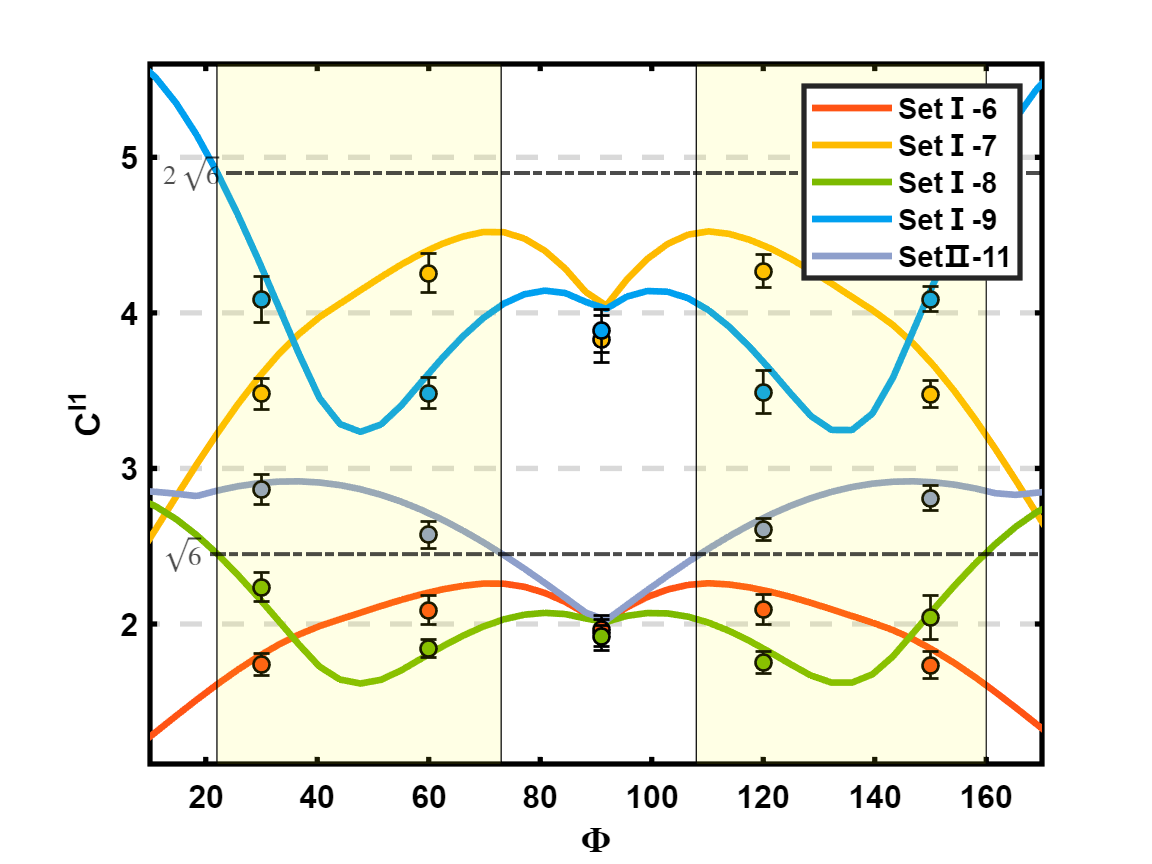

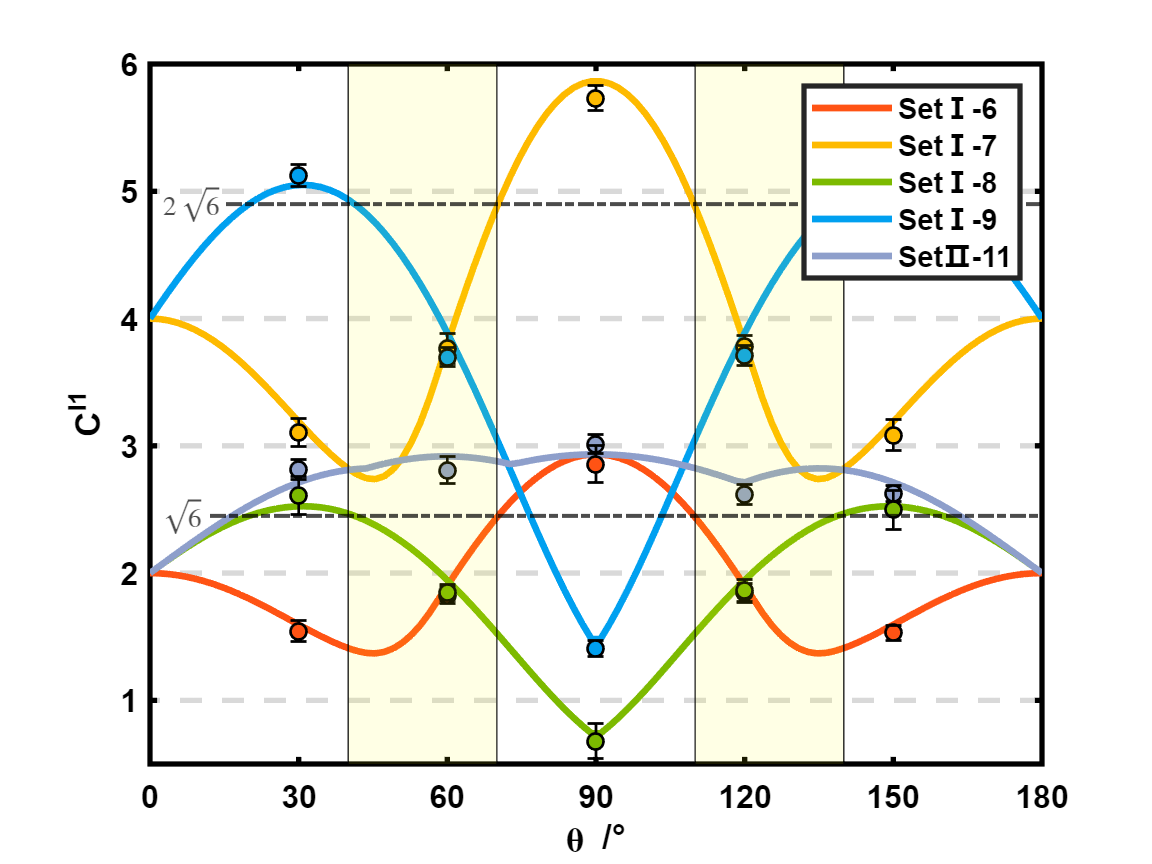

clc
clear;
close all;

H = [1,0]';
V = [0,1]';

%方位角
Wphi = linspace(0,2*pi);
%仰角
Wtheta = linspace(0,pi);

parfor i = 91:100

    m = matfile(sprintf('Woutput%d.mat',i),'writable',true);

    value = zeros(1,length(Wtheta),6);
    Theta = zeros(1,length(Wtheta),6);
    Phi = zeros(1,length(Wtheta),6);

    for j = 1:length(Wtheta)

        phi = Wphi(i);
        theta = Wtheta(j);

        x = sin(theta)*cos(phi);
        y = sin(theta)*sin(phi);
        z = cos(theta);
        W = x*kron(kron(V,H),H)+y*kron(kron(H,V),H)+z*kron(kron(H,H),V);
        rho = W*W';
    
        [value(1,j,1),Theta(1,j,1),Phi(1,j,1)] = find_direction3(rho);
        [value(1,j,2),Theta(1,j,2),Phi(1,j,2)] = find_direction4(rho);
        [value(1,j,3),Theta(1,j,3),Phi(1,j,3)] = find_direction5(rho);
        [value(1,j,4),Theta(1,j,4),Phi(1,j,4)] = find_direction6(rho);
        [value(1,j,5),Theta(1,j,5),Phi(1,j,5)] = find_direction7(rho);
        [value(1,j,6),Theta(1,j,6),Phi(1,j,6)] = find_direction8(rho);
        [value(1,j,7),Theta(1,j,7),Phi(1,j,7)] = find_directionA1(rho);
        [value(1,j,8),Theta(1,j,8),Phi(1,j,8)] = find_directionA2(rho);
        [value(1,j,9),Theta(1,j,9),Phi(1,j,9)] = find_directionA3(rho);
        [value(1,j,10),Theta(1,j,10),Phi(1,j,10)] = find_directionA4(rho);
    end
    i
    m.value = value;
    m.Theta = Theta;
    m.Phi = Phi;
end